# 2.4 Решение СЛАУ

**Лекция**

## **Общий вид систем линейных алгебраических уравнений (СЛАУ)**

СЛАУ, содержащая n неизвестных и m уравнений в общем виде может быть записана следующим образом:


$$$$
\left\{
\begin{array}{rcl}
x_1a_{11} + x_2a_{12}+ \cdot \cdot \cdot+ x_n a_{1n}&=&f_1\\
x_1a_{21} + x_2a_{22}+ \cdot \cdot \cdot + x_n a_{2n} &=&f_2\\
\cdot  \cdot \cdot \cdot \cdot \\
x_1a_{m1} + x_2a_{m2}+ \cdot \cdot \cdot + x_n a_{mn} &=&f_m\\
\end{array}
\right.
$$$$


Зададим вектор неизвестных величин как $x$, матрицу коэффициентов$$A$$ и вектор свободных членов $$f$$следующим образом:


$$$$  x =  \left(\begin{array}{ccc}x_1\\ x_2 \\ \vdots \\ x_n  \end{array}\right), A = \left(\begin{array}{ccc}
a_{11}& a_{12} &\ldots & a_{1n}\\
a_{21}& a_{22} &\ldots & a_{2n}\\
\vdots& \vdots &\ddots & \vdots\\
a_{m1}& a_{m2} &\ldots & a_{mn}
\end{array}\right),  f =  \left(\begin{array}{ccc} f_1\\ f_2 \\ \vdots \\ f_m  \end{array}\right).
$$$$


Тогда исходную систему можно представить в матричном виде:

$
Ax=f 
$       (1)

Если ранг матрицы коэффициентов $$\mathrm{rg}(A)$$ совпадает с количеством неизвестных $n$, то ненулевое решение системы существует и единственно. Если $\mathrm{rg}(A)<n$, то система называется недоопределённой решений системы бесконечно много, а если $\mathrm{rg}(A)>n$, то система называется переопределённой и не имеет точного решения. Для определения ранга матрицы используется команда `rank`.

A1 = [1 ,1 1, 1,1;       % матрица системы
     3 2 1 1 -3;
     0 1 2 2 6;
     5 4 3 3 -1];
f1 = [7; -2; 23; 12];    % вектор свободных членов
[A1,f1]                   % расширенная матрица

ans =      1     1     1     1     1     7
     3     2     1     1    -3    -2
     0     1     2     2     6    23
     5     4     3     3    -1    12


[rank(A1), rank([A1,f1])]    % Ранг меньше размеров матрицы, требуется её уменьшить

ans =      2     2


Чтобы привести матрицу (или расширенную матрицу $A|f$) к каноническому виду по методу Гаусса можно использовать функцию `rref` и таким образом уменьшать порядок матрицы:

[Canonic, order] = rref([A1,f1])      % метод Гаусса

Canonic =      1     0    -1    -1    -5   -16
     0     1     2     2     6    23
     0     0     0     0     0     0
     0     0     0     0     0     0


order =      1     2


A1_Reduced = Canonic(order,1:end-1)  % выделение приведённой матрицы 

A1_Reduced =      1     0    -1    -1    -5
     0     1     2     2     6


f1_reduced = Canonic(order,end)  % выделение приведённого свободного вектора

f1_reduced =    -16
    23


## Решение СЛАУ с помощью вычисления обратной матрицы

Если матрица $A$ диагональна и $\mathrm{rg}(A)=n$, то уравнение (1) можно решить, определив обратную матрицу к $A$:


$$x=A^{-1}f$$


Обратная матрица находится с помощью функции `inv`:

A2 = [3 -1  1;
     2 -5 -3;
     1  1 -1];
f2 = [4;-17;0];
x2 = inv(A2)*f2

x2 =      1
     2
     3


## Решение СЛАУ с помощью операции "\" (косого деления)

Вычисление обратной матрицы является не самым быстрым (с точки зрения скорости расчета) методом. К тому же, решение с помощью обратной матрицы невозможно в случае, если матрица не является квадратной. Существует множество альтернативных способов решения систем. Некоторые из этих методов ускоряют решение СЛАУ с квадратной матрицей, некоторые, например, предназначены для нахождения приближённого решения систем с переопределёнными матрицами. 

В MATLAB существует универсальная операция для решения СЛАУ - косое деление "`\`" или по-другому `mldivide`. При её вызове автоматически подбирается подходящий способ решения из встроенных в MATLAB способов. Некотрые из них будут рассмотрены ниже. 

Если имеется ввиду уравнение (1), то синтаксис будет иметь вид  `x = A\f`.

В случае $\mathrm{rg}(A)=n$, ответом является решение системы уравнений одним из методов (метод Холецкого, метод PLU ,метод QR)

x3 = A2\f2     % решение из предыдущего примера

x3 =     1.0000
    2.0000
    3.0000


В случае $\mathrm{rg}(A)<n$ (недоопределённая система) результатом работы оператора "`\`" является частное решение СЛАУ, имеющее не более $$\mathrm{rg}(A)$$ нулевых компонент:

x4 = A1_Reduced\f1_reduced    % матрица из примера с понижением порядка

x4 =     3.1667
         0
         0
         0
    3.8333


В случае $\mathrm{rg}(A)>n$ (переопрелелённая система) оператор "\" находит приближённое решение методом наименьших квадратов.

## **Метод Холецкого**

В случае, если матрица $$A$$ является **квадратной**, **симметричной** и **положительно-определённой**, то её можно единственным образом представить в виде: $A = L \cdot L^T = U^T \cdot U,$ где $L$ - нижняя треугольная матрица (все, что выше диагонали - нули), а $U$- верхняя треугольная матрица (все, что ниже диагонали - нули). Подставляя один из указанных способов разложения в уравнение системы (1) получим:

$L L^Tx=f \Rightarrow 
\left\{
\begin{array}{rcl}
L  y  = f\\
L^T x=y\\
\end{array}
$ или $U^TUx=f \Rightarrow 
\left\{
\begin{array}{rcl}
U^T y  = f\\
U  x=y\\
\end{array}
$.

Из-за треугольности матриц обе системы решаются обычной подстановкой. Для такого разложения в MATLAB есть функция `chol`:

f3 = [-2; 3; 1; 0];
A3 = pascal(4)      % симметричная положительно-определённая квадратная матрица

A3 =      1     1     1     1
     1     2     3     4
     1     3     6    10
     1     4    10    20


U3 = chol(A3)       % Преобразование Холецкого

U3 =      1     1     1     1
     0     1     2     3
     0     0     1     3
     0     0     0     1


U3'*U3-A3           % разложение корректно

ans =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


## **Метод LUP-разложения**

Если матрица $$A$$ является **квадратной**, то для неё существует и единственно так называемое LUP-разложение вида $PA = L  U$, где $L$-верхняя треугольная матрица, $U$ - нижняя треугольная матрица, а $P$ - матрица перестановок.

Сначала домножим левую и правую часть исходного уравнения системы (1) на $P$:  

$PAx=Pf \Rightarrow LUx=Pf \Rightarrow \left\{
\begin{array}{rcl}
L  y  =P f\\
U x=y.\\
\end{array} $. 

Также как и в случае разложения Холецкого обе системы решаются простой подстановкой вследствие треугольности матриц. В MATLAB для такого разложения предусмотрена функция `lu`:

[L, U, P] = lu(A2)

L =     1.0000         0         0
    0.6667    1.0000         0
    0.3333   -0.3077    1.0000


U =     3.0000   -1.0000    1.0000
         0   -4.3333   -3.6667
         0         0   -2.4615


P =      1     0     0
     0     1     0
     0     0     1


L*U - P*A2         % ошибка разложения имеет незначительна и имеет порядок 10^-15

ans = 	1.0e+-15 *

         0         0         0
         0         0         0
         0         0   -0.2220


## **Метод QR-разложения**

Рассматриваемое разложение может быть применено как для квадратной, так и для прямоугольной матрицы $$A$$. 

Матрица $$A$$ размерами $m \times n$ может быть представлена в виде $A = Q\cdot R$, где $Q$ - ортонормированная матрица с размерами $m \times m$ (ортонормированность это $Q^{-1} = Q^T$ и $QQ^T=E$, где $E$ - единичная матрица), а $R$ - матрица с размерами $m \times n$, чьи компоненты ниже главной диагонали - нулевые. Преобразования исходного уравнения системы (1) выглядят так:

$Ax=f \Rightarrow QRx=f \Rightarrow Rx = Q^Tf$.

Если матрица $$A$$ - квадратная, то $R$ - верхняя треугольная матрица и система решается обычной подстановкой. В MATLAB предусмотрена для qr-разложения функция `qr`:

A4 = randi([-10, 10],4); 
f4 = randi([-10, 10], 3,1)

f4 =      7
    -5
     2


A4 = A4(1:3,:)

A4 =      4     4    -1    -3
     3    -6    -1     3
     9    -8     3    -2


[Q, R] = qr(A4)     % QR-разложение

Q =    -0.3885    0.8468   -0.3633
   -0.2914   -0.4869   -0.8234
   -0.8742   -0.2141    0.4359


R =   -10.2956    7.1875   -1.9426    2.0397
         0    8.0212   -1.0021   -3.5731
         0         0    2.4945   -2.2523


Q'- inv(Q)      % проверка ортогональности, ошибка 10^-15

ans = 	1.0e+-15 *

    0.2776         0    0.3331
         0   -0.1665   -0.1388
    0.1110   -0.1110    0.0555


Q*Q'        % проверка ортонормированности

ans =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000    1.0000


Q*R - A4    % проверка правильности qr-разложения, ошибка 10^-14

ans = 	1.0e+-14 *

   -0.0444         0   -0.0444    0.0888
   -0.0444   -0.0888   -0.0222         0
   -0.1776    0.0888         0    0.0444


## **Функция**` linsolve`

Для того, чтобы выбрать метод решения СЛАУ, оператор косого деления "`\`" (или функция `mldivide`) предварительно проверяет, соответствие матрицы $$A$$ тому или иному алгоритму. На эту проверку уходит определённое время, которое могло быть сэкономлено, если бы пользователь заранее знал тип матрицы и соответствующий ей способ решения линейной системы. Для таких случаев существует функция `linsolve`, позволяющая задавать способ решения системы вручную. Однако, если способ не подходит для решения введенной матрицы, программа выдаст ошибку. 

По умолчанию используется LUP-метод для квадратных для квадратных матриц, однако дополнительно можно тип матрицы $$A$$. Ниже представлена классификация матриц:

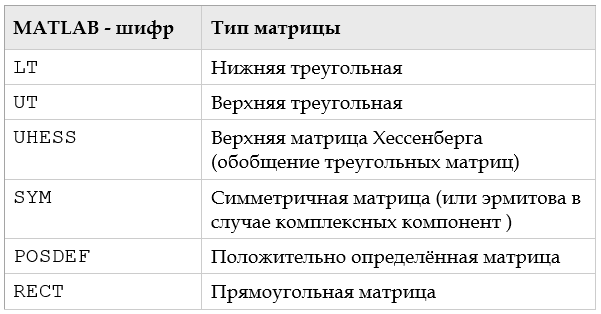

Примеры использования функции `linsolve`: 

linsolve(A4,f4)     % недоопределённая система решена с помощью qr-разложения, найдено частное решение

ans =     0.8835
    1.1117
    0.9806
         0


opts3.POSDEF = true;
opts3.SYM    = true;
linsolve(A3,f3,opts3) % решение системы с симметричной положительноопределённой матрицей методом Холецкого

ans =    -22
    43
   -31
     8


## **Полное решение недоопределённой системы**

В случае недоопределенной СЛАУ ($\mathrm{rg}(A)<n$) имеет место бесконечное число решений, которые в совокупности представляют собой сумму линейной оболочки $n - \mathrm{rg}(A)$ линейно независимых решений однородной системы ($Ax = 0$) и частного решения системы (1). Общий вид решения имеет вид $x = C_1r_1 + C_2r_2 + \cdot \cdot \cdot C_{n-m}r_{n-m}+p$, где $C_i$ - произвольные действительные коэффициенты, $r_i$ - линейно независимые решения $(i = \overline{1,n-m})$, а вектор $p$ является каким-либо частным решением исходной системы (1). 

Для нахождения набора линейно независимых решений $r_i $ однородной системы можно использовать функцию `null`. По умолчанию все решения отображаются ортонормированными. Для отображения компонентов в рациональной форме следует добавить параметр `'r'` (rational basis). Пример использования `null`:

null(A1,'r') % искомые вектора-столбцы в рациональной форме

ans =      1     1     5
    -2    -2    -6
     1     0     0
     0     1     0
     0     0     1


null(A1)    % искомые вектора-столбцы в ортонормированной форме

ans =     0.7462    0.1027    0.0000
   -0.5304    0.6704    0.0000
   -0.2281   -0.4960   -0.7071
   -0.2281   -0.4960    0.7071
    0.2405    0.2190    0.0000


Для нахождения частного решения $p$ можно воспользоваться численным (достаточно точным) или аналитическим спобом.

Численный способ подразумевает использование оператора обратного деления "`\`", которое позволяет численно получить одно из частных решений:

p =  A1\f1       % предупреждение показывает, что ранг меньше размеров матрицы

p =     3.1667
         0
         0
         0
    3.8333


Аналитический способ подразумевает преобразование расширенной матрицы $A|f$ по методу Гаусса с помощью встроенной MATLAB функции `rref`:

G1 = rref([A1,f1])   % метод Гаусса 

G1 =      1     0    -1    -1    -5   -16
     0     1     2     2     6    23
     0     0     0     0     0     0
     0     0     0     0     0     0


p = G1(:,end)       % последний столбец приведённой матрицы является частным решением

p =    -16
    23
     0
     0


## Решение переопределённой системы

Точного решения СЛАУ $\mathrm{rg}(A)>n$ не существует, однако существует целый класс задач, который решается с помощью приближённого решения переопределённых систем. Оператор обратного деления "`\`" определяет приближённое решение используя метод наименьших квадратов. Ниже представлен пример решения неопределённой системы. 

Пусть имеется измерение во времени какого-либо процесса:

t = [0 .3 .8 1.1 1.6 2.3]';   
f = [.82 .72 .63 .60 .55 .50]';
%B = [t,f]

Известно, что аналитическое выражение процесса имеет вид $f(t) = c_1+c_2e^{-t}$, где $c_1$ и $c_2$ - искомые коэффициенты. Из данных их требуется приближённо найти методом наименьших квадратов.

Для этого формируется матрица переопределённой системы:

A = [ones(size(t)) exp(-t)]

A =     1.0000    1.0000
    1.0000    0.7408
    1.0000    0.4493
    1.0000    0.3329
    1.0000    0.2019
    1.0000    0.1003


И определяется приближённое решение системы:

c = A\f

c =     0.4760
    0.3413


Приближённые коэффициенты найдены, графически это приближение будет иметь следующий вид:

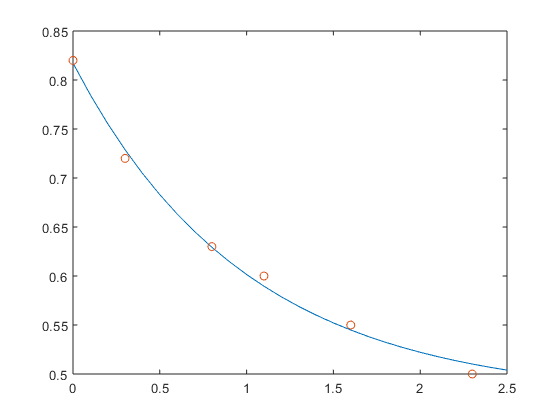

T = (0:0.1:2.5)';
F = [ones(size(T)) exp(-T)]*c;
plot(T,F,'-',t,f,'o')

Из графика видно, что найденное решение не является точным, однако оно приближено к экспериментальным данным. 